# EJERCICIO 1

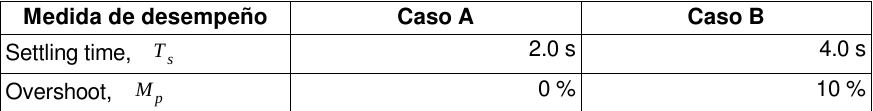

clc; clear; close all;

## 1. ¿Cuáles son los valores de ωn , ζ para el caso A?

$\zeta = \frac{1}{\sqrt{1+ \left(\frac{\pi}{\delta}\right)^2}$     ;   $\delta = ln\left(M_p\right)$

 
$$T_s \approx \frac{4}{\zeta\omega_n}$$


Mp_A     = 0.0; % overshoot caso A
zeta_A   = 1.0; % amortiguamiento caso A
Ts_A     = 2.0; % tiempo de asentamiento caso A
wn_A     = 5.8/(Ts_A); % frecuencia natural A
disp(zeta_A);

     1



disp(wn_A);

    2.9000



## 2. ¿Dónde se ubican los polos del polinomio deseado?

sys_A = tf(wn_A^2, [1 2*zeta_A*wn_A wn_A^2])

sys_A =
 
         8.41
  ------------------
  s^2 + 5.8 s + 8.41
 
Continuous-time transfer function.



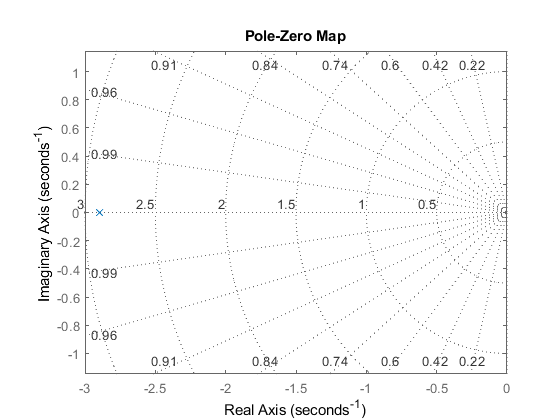

pzmap(sys_A); grid on; axis('equal');

## 3. Grafique la respuesta al escalón.

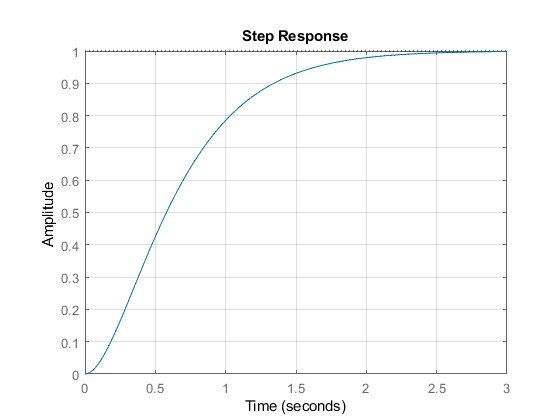

step(sys_A); grid on;

stepinfo(sys_A)

ans = struct with fields:
        RiseTime: 1.1579
    SettlingTime: 2.0117
     SettlingMin: 0.9020
     SettlingMax: 0.9994
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9994
        PeakTime: 3.3900


## 4. ¿Cuáles son los valores de ωn y ζ para el caso B?

Mp_B     = 0.10; % overshoot caso B
delta_B  = log(Mp_B); % Decremento logarítmico B
zeta_B   = 1/sqrt(1 + (pi/delta_B)^2);  % Relación de amortiguamiento crítico B
Ts_B     = 4.0; % tiempo de asentamiento caso B
wn_B     = 4/(Ts_B*zeta_B); % frecuencia natural B
disp(zeta_B);

    0.5912



disp(wn_B);

    1.6916



## 5. ¿Dónde se ubican los polos del polinomio deseado?

sys_B = tf(wn_B^2, [1 2*zeta_B*wn_B wn_B^2])

sys_B =
 
        2.862
  -----------------
  s^2 + 2 s + 2.862
 
Continuous-time transfer function.



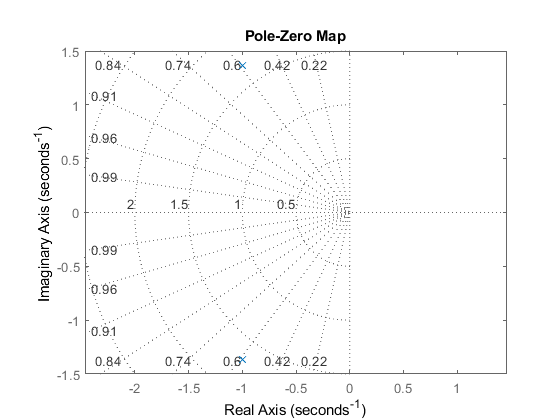

pzmap(sys_B); grid on; axis('equal');

## 6. Grafique la respuesta al escalón.

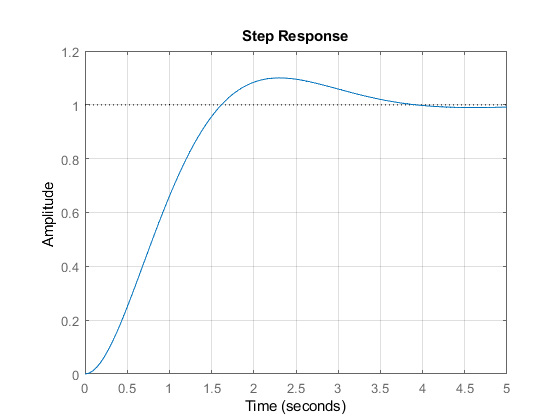

step(sys_B); grid on;

stepinfo(sys_B)

ans = struct with fields:
        RiseTime: 1.0842
    SettlingTime: 3.5031
     SettlingMin: 0.9025
     SettlingMax: 1.1000
       Overshoot: 10.0000
      Undershoot: 0
            Peak: 1.1000
        PeakTime: 2.3026
